clear
s = tf('s');
G = s/(s^3+5*s^2+4*s+20) %zpk(0,[0,-1,-4],20)%20/s/(s+1)/(s+4)

G =
 
            s
  ----------------------
  s^3 + 5 s^2 + 4 s + 20
 
연속시간 전달 함수입니다.



pole(G)

ans =            -5 +          0i
    1.301e-15 +          2i
    1.301e-15 -          2i


zero(G)

ans =      0


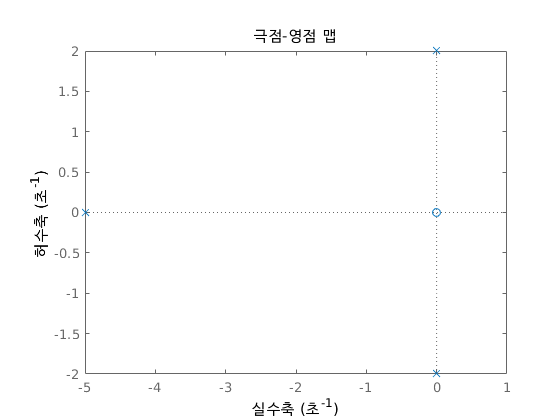

pzmap(G)

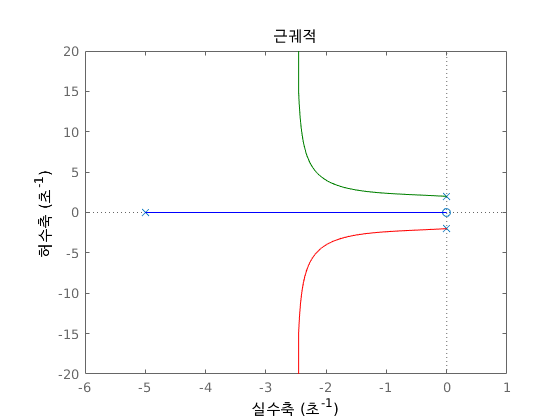

rlocus(G)

clear, syms s
factor(s^3+5*s^2+4*s+20,'FactorMode',"complex")

$$ans = \left(\begin{array}{ccc} s+5.0 & s+2.0\,\mathrm{i} & s-2.0\,\mathrm{i} \end{array}\right)$$

expand(s*(s+1)*(s+4))

$$ans = s^{3}+5\,s^{2}+4\,s$$

%expand(s*(s+1)*(s+4))
%factor(s^3+5*s+(4+k)*s+20)

fx = 1/10*s+1/4-1/s^2

$$fx = \frac{s}{10}-\frac{1}{s^{2}}+\frac{1}{4}$$

%fx = fx*20*s^2
factor(2*s^3+5*s^2-20, 'FactorMode',"complex")

$$ans = \left(\begin{array}{cccc} 2.0 & s-1.5678894233545499546384830279309 & s+2.0339447116772749773192415139654-1.4970202777829981103968399985693\,\mathrm{i} & s+2.0339447116772749773192415139654+1.4970202777829981103968399985693\,\mathrm{i} \end{array}\right)$$

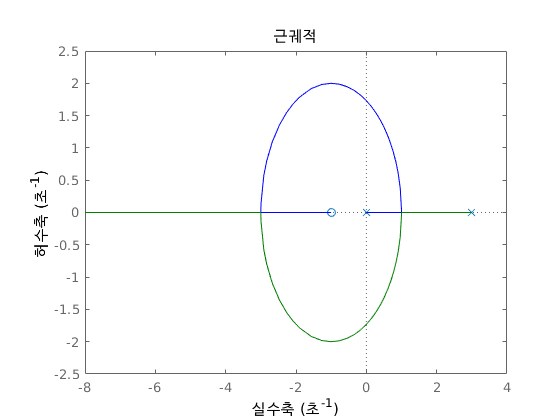

clear, hold off

s = tf('s')

s =
 
  s
 
연속시간 전달 함수입니다.



G = (s+1)/s/(s-3)

G =
 
    s + 1
  ---------
  s^2 - 3 s
 
연속시간 전달 함수입니다.



pole(G)

ans =      0
     3


zero(G)

ans = -1

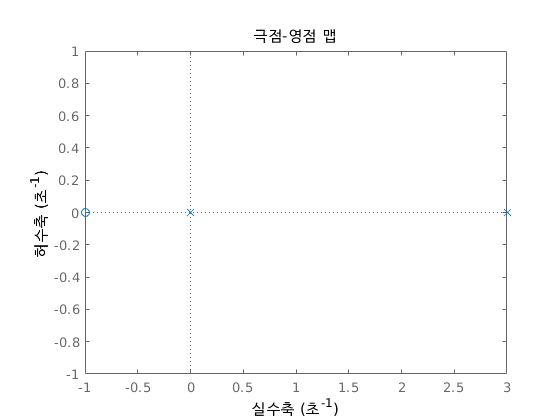

pzmap(G)

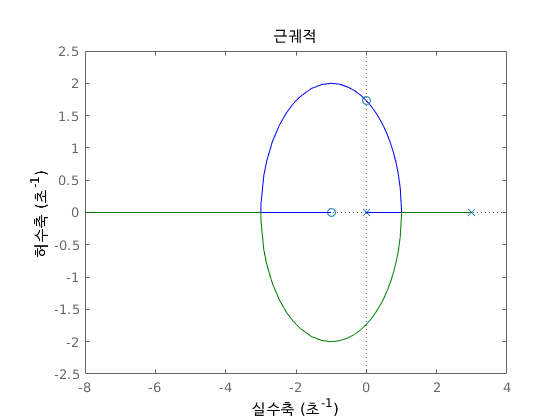

rlocus(G)
hold on
plot(0,sqrt(3),'o');